## Housekeeping

Clear all figures, data, and set a timer.

close all
clear
clc

% Set timer
h = tic;

## Prep Work

This is where we load all of our participant files directories', as well as parameters for processing the output of the ECHT device and exclude participant's with artifacts.

% Load current data table
datafilename = '/Applications/Toolbox/MATLAB/TwoPhaseExp_table.mat';    %% Changed for Windows
load(datafilename);
dataTable = sortrows(dataTable);

% Prep ECHT Parameters - speciify wavelet frequency range, resolution + 
% low cycles creates wide frequency ranges
params = echtparams('freqs', [2 70], 'steps', 70, 'cycles', [5 12],'tWin', [-0.5 0]);

% Load subject directories
pname = genpath('/Applications/Toolbox/SubjectData');  %% Changed for Windows
pname = strsplit(pname,':')'; %% Switched

% Locate Random Phase ERP or TwoPhase datasets
% pname = pname(contains(pname,'ISI750ms85dB') & ~contains(pname,'(Low'));
pname = pname(contains(pname,'TwoPhaseERP85dB') & ~contains(pname,'(Low'));

% Select subjects to exclude from group analysis
exSub = {'Sub_151','Sub_152','126'}; 
if(~isempty(exSub))  
    pname = pname(~contains(pname,exSub)); % exclude subject(s)
end

% Setup pyversion for fooof
pyenv;
% pyenv(Version="c:\users\seahorse\appdata\local\programs\python\python38\python.exe");


## Gather Data

This is where we loop through each subject, and grab their prestimulus power for each condition, showing that they are in fact equal, as well as consistent with prior work (Iemi et al., 2019).

for k = 1:(length(pname))

    % Get subject index
    tmp = strsplit(pname{k},filesep);
    Sub_ID = tmp{contains(tmp,'Sub_')};
    subIdx = contains(dataTable.SubID,Sub_ID([5:end]));

    % Setup alpha center frequency
    params.alphaCF = dataTable(subIdx,:).IAF(1);


    % Process data
    [ERP,params2] = batchERP(pname{k},params);
    fs = ERP.fs(1);
    t = ERP.t0;


    % Reformat Morlet Transform
    erp = permute(ERP.erp,[3 1 2]);

    % Check order of optimal/pessimal phase list in ERP structure against the
    % calculated phases in 'dataTable.' Fix wrap-around error if necessary
    if(dataTable(subIdx,:).OptPhase > dataTable(subIdx,:).PesPhase)
        ERP.setPhases = ERP.setPhases([2 1]);
    end

    % Sort trial types & good trials
    for i = 1:2
        pIdx{i} = intersect(ERP.goodTrials,...
                  find(round(ERP.echtPhaseLabel)==ERP.setPhases(i)));

        % Get trail type
        tmp = squeeze(median(erp(pIdx{i},:,:)));
        
        % Power spectrum
        frange = [1 50];
        settings = struct('aperiodic_mode', 'knee');
        [pxx, f] = pspectrum(tmp, fs, 'FrequencyLimits', frange);

        % each electrode
        for j = 1:2
            mdl = fooof(f, pxx(:,j), frange, settings, 1);
    
            % Detrend
            pyy(k,i,:,j) = mdl.fooofed_spectrum - mdl.ap_fit;
            f = mdl.freqs;
        end

    end
end

Loading .csv log data...COMPLETE
Bandpass filtering raw EEG signal to 2-34 Hz...COMPLETE
Epoch continuous EEG data...Bandpass filtering raw EEG signal to alpha 7.34-12.23 Hz (zero-phase)...COMPLETE
Bandpass filtering raw EEG signal to theta 3.75-6.25 Hz (zero-phase)...COMPLETE
COMPLETE
COMPLETE
Loading .csv log data...COMPLETE
Bandpass filtering raw EEG signal to 2-34 Hz...COMPLETE
Epoch continuous EEG data...Bandpass filtering raw EEG signal to alpha 7.34-12.23 Hz (zero-phase)...COMPLETE
Bandpass filtering raw EEG signal to theta 3.75-6.25 Hz (zero-phase)...COMPLETE
COMPLETE
COMPLETE


Unable to resolve the name 'py.numpy.array'.

Error in fooof (line 43)
    freqs = py.numpy.array(freqs);

## Post Process

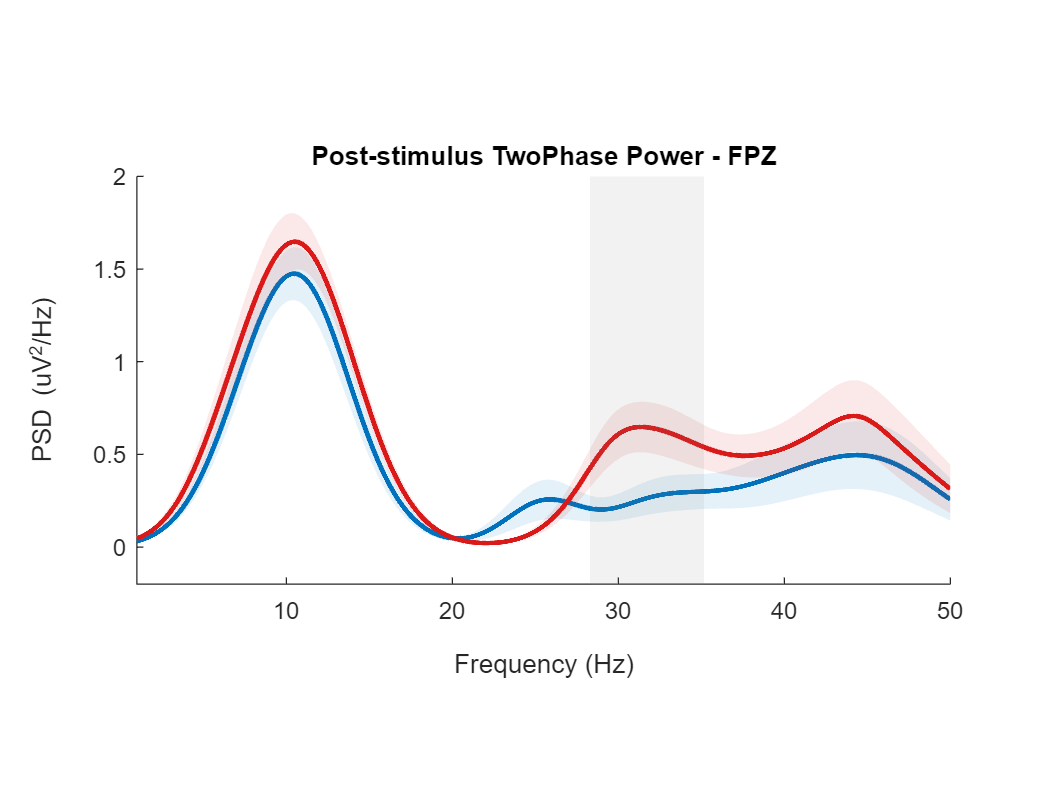

% Permutation test parameters
iter = 5000;
correction = 'cluster';
circ = 0;
trial_level = 0;

% Permute
trough = squeeze(pyy(:,1,:,:));
peak = squeeze(pyy(:,2,:,:));
% [ppwr,~,~] = npperm(trough, peak, iter, correction, circ, trial_level);

% Resize frequency vector
freqs = [f , fliplr(f)];

% Get colors
color = [0.0000 0.4470 0.7410
         0.8500 0.10 0.0980];

% First set
f0 = figure;

% Get mean and standard error
mu = squeeze(mean(pyy(:,:,:,1)));
se = squeeze(std(pyy(:,:,:,1))./sqrt(19));

% Resize standard errors
se = [mu - se, fliplr(mu + se)];

% Plot Trough Spectrum
plot(f, mu(1,:),'color', color(1,:), 'linewidth', 2)
hold on
fill(freqs, se(1,:), color(1,:),'edgecolor','none','facealpha', 0.1)
xlim([1 50])
xlabel('Frequency (Hz)')
ylabel('PSD (uV^2/Hz)')
ylim([-0.2 2])
box off
axis square
pbaspect([2 1 1])
hold on

% Plot Peak Spectrum 
plot(f, mu(2,:),'color', color(2,:), 'linewidth', 2)
hold on
fill(freqs, se(2,:), color(2,:),'edgecolor','none','facealpha', 0.1)
xlim([1 50])
title('Post-stimulus TwoPhase Power - FPZ')
xlabel('Frequency (Hz)')
ylabel('PSD (uV^2/Hz)')
ylim([-0.2 2])
box off
axis square
pbaspect([2 1 1])
hold on

grey  = [0.5 0.5 0.5];
[x, y] = clusts4plot(ppwr(:,1), 0.05, [-10 10]);
for i = 1:size(x,1)
    patch(f(x(i,:)), y, grey,'LineStyle','none','FaceAlpha',0.1);
    hold on
end



% Second set
f1 = figure;

% Get mean and standard error
mu = squeeze(mean(pyy(:,:,:,2)));
se = squeeze(std(pyy(:,:,:,2))./sqrt(20));

% Resize standard errors
se = [mu - se, fliplr(mu + se)];

% Plot Trough Spectrum
plot(f, mu(1,:),'color', color(1,:), 'linewidth', 2)
hold on
fill(freqs, se(1,:), color(1,:),'edgecolor','none','facealpha', 0.1)
xlim([1 50])
xlabel('Frequency (Hz)')
ylabel('PSD (uV^2/Hz)')
ylim([-0.2 2])
box off
axis square
pbaspect([2 1 1])
hold on

% Plot Peak Spectrum 
plot(f, mu(2,:),'color', color(2,:), 'linewidth', 2)
hold on
fill(freqs, se(2,:), color(2,:),'edgecolor','none','facealpha', 0.1)
xlim([1 50])
title('Post-stimulus TwoPhase Power - FZ')
xlabel('Frequency (Hz)')
ylabel('PSD (uV^2/Hz)')
ylim([-0.2 2])
box off
axis square
pbaspect([2 1 1])
hold on

grey  = [0.5 0.5 0.5];
[x, y] = clusts4plot(ppwr(:,2), 0.05, [-10 10]);
for i = 1:size(x,1)
    patch(f(x(i,:)), y, grey,'LineStyle','none','FaceAlpha',0.1);
    hold on
end

% Save Figure
svpath = 'C:\Toolbox\MATLAB\Figures';
print(f0, fullfile(svpath, 'Fooofed Post-Stimulus Spectrogram FPZ'),'-dsvg');
print(f0, fullfile(svpath, 'Fooofed Post-Stimulus Spectrogram FPZ'),'-dpng');

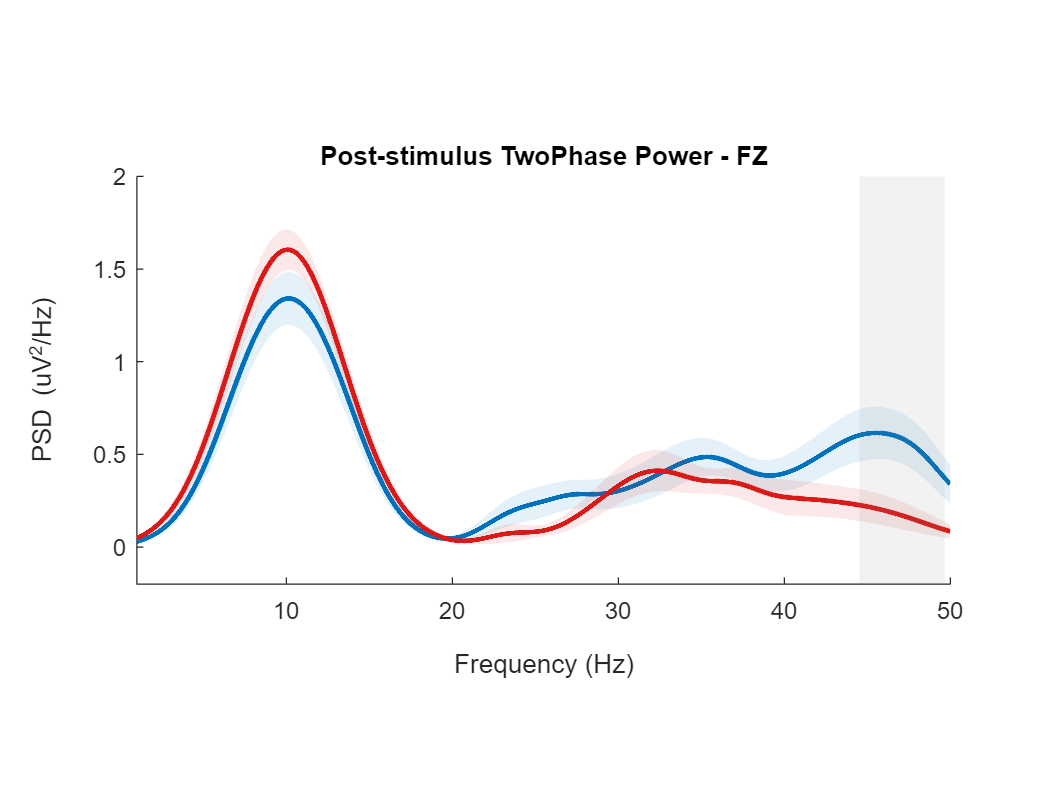

print(f1, fullfile(svpath, 'Fooofed Post-Stimulus Spectrogram Fz'),'-dsvg');
print(f1, fullfile(svpath, 'Fooofed Post-Stimulus Spectrogram  Fz'),'-dpng');



% Timing is everything
sprintf('Time to run: %d', toc(h));